# 案例：差分进化算法实现指数拟合

clear;clc;
t = 0.2*(1:3000)';
data = 400*exp(-t/5) + 10*randn(size(t));
tic;
p = DE_ExpFit(t, data)

p =   402.8457    4.9041    0.0000


toc;

历时 0.687172 秒。


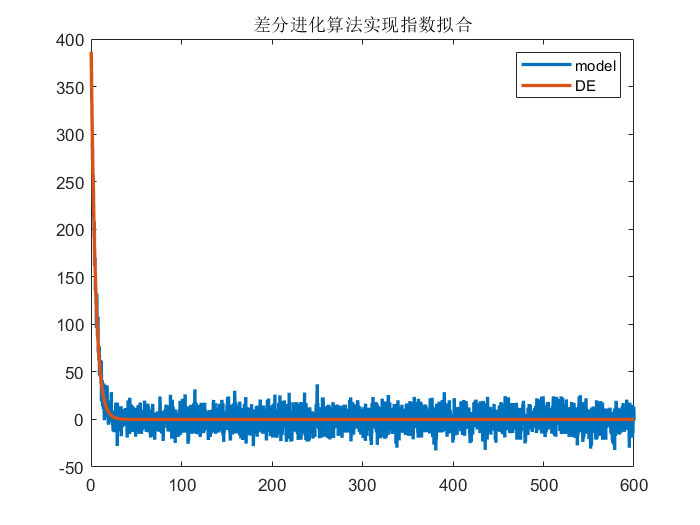

fit = p(1)*exp(-t/p(2)) + p(3);
plot(t, data, t, fit, 'LineWidth', 2)
legend('model', 'DE');
title('差分进化算法实现指数拟合');

function [x_opt, y_opt] = DE_ExpFit(t, Et)
%{
函数功能：差分进化算法实现指数拟合：y = a*exp(-x/b) + c
输入：
  t：自变量；
  Et：因变量；
输出：
  x_opt：最优解；
  y_opt：适应度（目标函数值）；
%} 
% 初始值
NP = 50;                          % 种群数量
D = 3;                            % 变量维度
G = 200;                          % 最大进化代数
F0 = 0.5;                         % 初始变异算子
CR = 0.9;                         % 交叉算子
max_sig = max(Et);
Xmin = [0.5*max_sig, -2, 0];           % 下限
Xmax = [1.5*max_sig, 4, 0.5*max_sig];  % 上限；
%%%%%%%%%%%%%  赋初值 %%%%%%%%%%%%%
Ob = zeros(NP, 1);
Ob1 = zeros(NP, 1);
v = zeros(NP, D);                    % 变异种群
u = zeros(NP, D);                    % 选择种群
x = rand(NP, D).*repmat(Xmax - Xmin, NP, 1) + repmat(Xmin, NP, 1);
%%%%%%%%%%%%%  计算目标函数 %%%%%%%%%%%%%
for m = 1 : NP
    Ob(m) = Obj_Fit(x(m, :), t, Et);
end
y_opt = zeros(1, G);
%%%%%%%%%%%%%  差分进化循环 %%%%%%%%%%%%%
for gen = 1 : G
    %%%%%%%%%%%%%  变异操作 %%%%%%%%%%%%%
    %%%%%%%%%%%%%  自适应变异算子 %%%%%%%%%
    lamda = exp(1 - G/(G + 1 - gen));
    F = F0*2^lamda;
    %%%%%%%%%%  r1、r2、r3和m互不相同 %%%%%%%%%%
    for m = 1 : NP
        r1 = randi([1, NP], 1);
        while r1 == m
            r1 = randi([1, NP], 1);
        end
        r2 = randi([1, NP], 1);
        while r2 == m || r2 == r1
            r2 = randi([1, NP], 1);
        end
        r3 = randi([1, NP], 1);
        while r3 == m || r3 == r2 || r3 == r1
            r3 = randi([1, NP], 1);
        end
        v(m, :) = x(r1, :) + F*(x(r2, :) - x(r3, :));
    end
    %%%%%%%%%%%%%  交叉操作 %%%%%%%%%%%%%
    r = randi([1, D], 1);
    for n = 1:D
        cr = rand;
        if cr <= CR || n == r
            u(:, n) = v(:, n);
        else
            u(:, n) = x(:, n);
        end
    end
    %%%%%%%%%%%%%  边界条件的处理 %%%%%%%%%%%%%
    % ①范围内随机值
       for n = 1:NP
          for m = 1:D
             if u(n, m) < Xmin(m) || u(n, m) > Xmax(m)
                u(n, m) = rand*(Xmax(m) - Xmin(m)) + Xmin(m);
             end
          end
       end
    % ②边界吸收
%     for n = 1 : NP
%         for m = 1 : D
%             if u(n, m) < Xmin(m)
%                 u(n, m) = Xmin(m);
%             end
%             if u(n, m) > Xmax(m)
%                 u(n, m) = Xmax(m);
%             end
%         end
%     end
    %%%%%%%%%%%%%  选择操作 %%%%%%%%%%%%%
    for m = 1 : NP
        Ob1(m) = Obj_Fit(u(m, :), t, Et);
    end
    for m = 1 : NP
        if Ob1(m) < Ob(m)
            x(m, :) = u(m, :);
        end
    end
    for m = 1 : NP
        Ob(m) = Obj_Fit(x(m, :), t, Et);
    end
    y_opt(gen) = min(Ob);
end
[~, Index] = min(Ob);
x_opt = x(Index, :);
x_opt(2) = 10^(x_opt(2));
end

% 目标函数
function fitError = Obj_Fit(p0, t ,Et)
A = p0(1);
B = p0(2);
C = p0(3);
f = A*exp(-t/10^B)  + C;  
fitError = norm(Et - f);
end